# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# Second Partial Examination -  A.Y. 2024/2025

**June 6, 2025**

# Design of a Proper Controller for a Plant with a Parameter Affected by  Interval Uncertainty

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

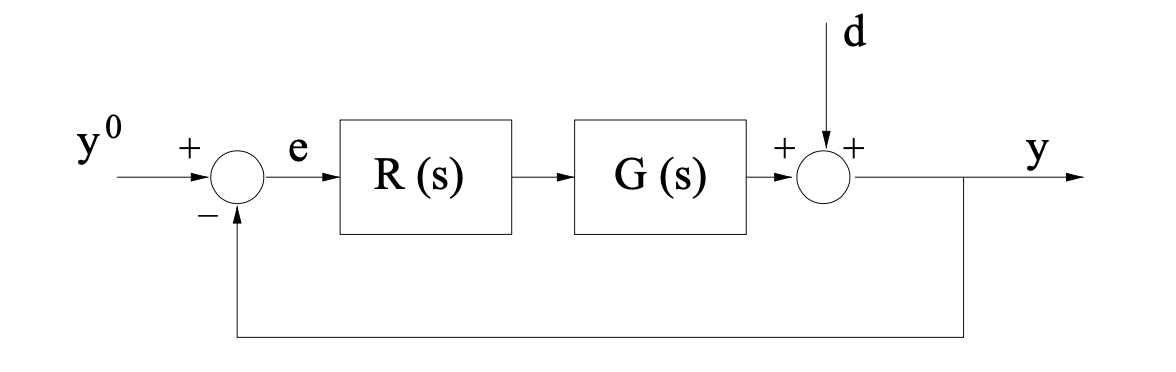	

where $G(s)$ is given by                


$$G(s) = 10\,\frac{\left(s+1 \right)\,\left(s+200\right)}{\left(s^2+20B\,s+100\right)\,\left(s+250\right)}\;,\quad B \in \big[0.005\,,\; 1.0 \big]$$


**Note**: This means that the system has a transfer function with two complex conjugate poles, the natural pulsation of which is known exactly, but the exact damping $\bar B$ is not known. All that is known of the eﬀective $B$ damping (which is unknown) is that it takes on a value contained in the assigned range $\big[0.005\,,\;1.0 \big]$ .

## **Question**		

**Q1**: Design a **proper** **controller** $C(s)$ such that all following requirements are simultaneously met: 

- Zero steady-state error in unit step response (closed-loop) $e(\infty) =0$, against disturbances given by 


$$\left\{ \begin{array}{rcl}
y^o(t) &=& 1(t) \\
d(t) &=& A\cdot 1(t)\,,\; A \in \mathbb{R}
\end{array} \right. \quad \Longrightarrow \quad e_{\infty} = 0
$$


            where $\mathbf{1}(t)$ denotes the unit step function;

- phase margin greater than or equal to $30^\circ$: $\varphi_m \ge 30^{\circ}$;

- settling time [at $1\%$ as usual] in the (closed-loop) unit step output less than or equal to $30$ seconds: $t_{s\,1\%} \le 30$ sec.

### Hint

How to handle the unknown damping factor $B$? A good practice is to identify the **worst-case scenario** and design the controller $C(s)$ according to that scenario.

## Solution

Initialisation code (clearing the MATLAB workspace, adding the path of the BodeDiagram subfolder to the MATLAB search-path)

clear variables

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

### Preliminary Analysis


$$G(s) = 10\,\frac{\left(s+1 \right)\,\left(s+200\right)}{\left(s^2+20B\,s+100\right)\,\left(s+250\right)}\;,\quad B \in \big[0.005\,,\; 1.0 \big]$$


According to (Q1.1), the regulator must have a pole at $s=0$: $\quad C_1(s) = \frac{\mu_C}{s}\;,\quad \mu_C >0$

dampMIN = 0.005; dampMAX = 1.0;
dampR = 0.5;

% static regulator, according to (Q1,1)
muC = 1;
C1s = muC/s;

% what is the worst-case scenario?
Gs1 = 10*(s+1)*(s+200)/(s^2+20*dampMIN*s+100)/(s+250);
Gs2 = 10*(s+1)*(s+200)/(s^2+20*dampMAX*s+100)/(s+250);
Gs3 = 10*(s+1)*(s+200)/(s^2+20*dampR*s+100)/(s+250);

Ls1 = C1s*Gs1;
Ls2 = C1s*Gs2;
Ls3 = C1s*Gs3;


Let's analyse the (Q1.3) requirement:


$$t_{s\,1\%} \le 10 \quad \Longleftrightarrow \quad 
\left\{ \begin{array}{rclcrclcrcl}
\varphi_m &>& 75^{\circ} &\Longrightarrow & t_{s\,1\%}&=&\frac{4.6}{\omega_c} \le 30 &\Longrightarrow & \omega_c &\ge &\frac{46}{300} \\ \\
\varphi_m &<& 75^{\circ} &\Longrightarrow &  t_{s\,1\%}&=&\frac{4.6}{\xi\,\omega_n} \approx \displaystyle \frac{4.6}{\frac{\varphi_m}{100}\,\omega_c} \le 30 &\Longrightarrow & \varphi_m\cdot \omega_c &\ge& \frac{46}{3}
\end{array} \right. \qquad (*)$$


Consider the first scenario ( $\varphi_m > 75^{\circ}$ ):

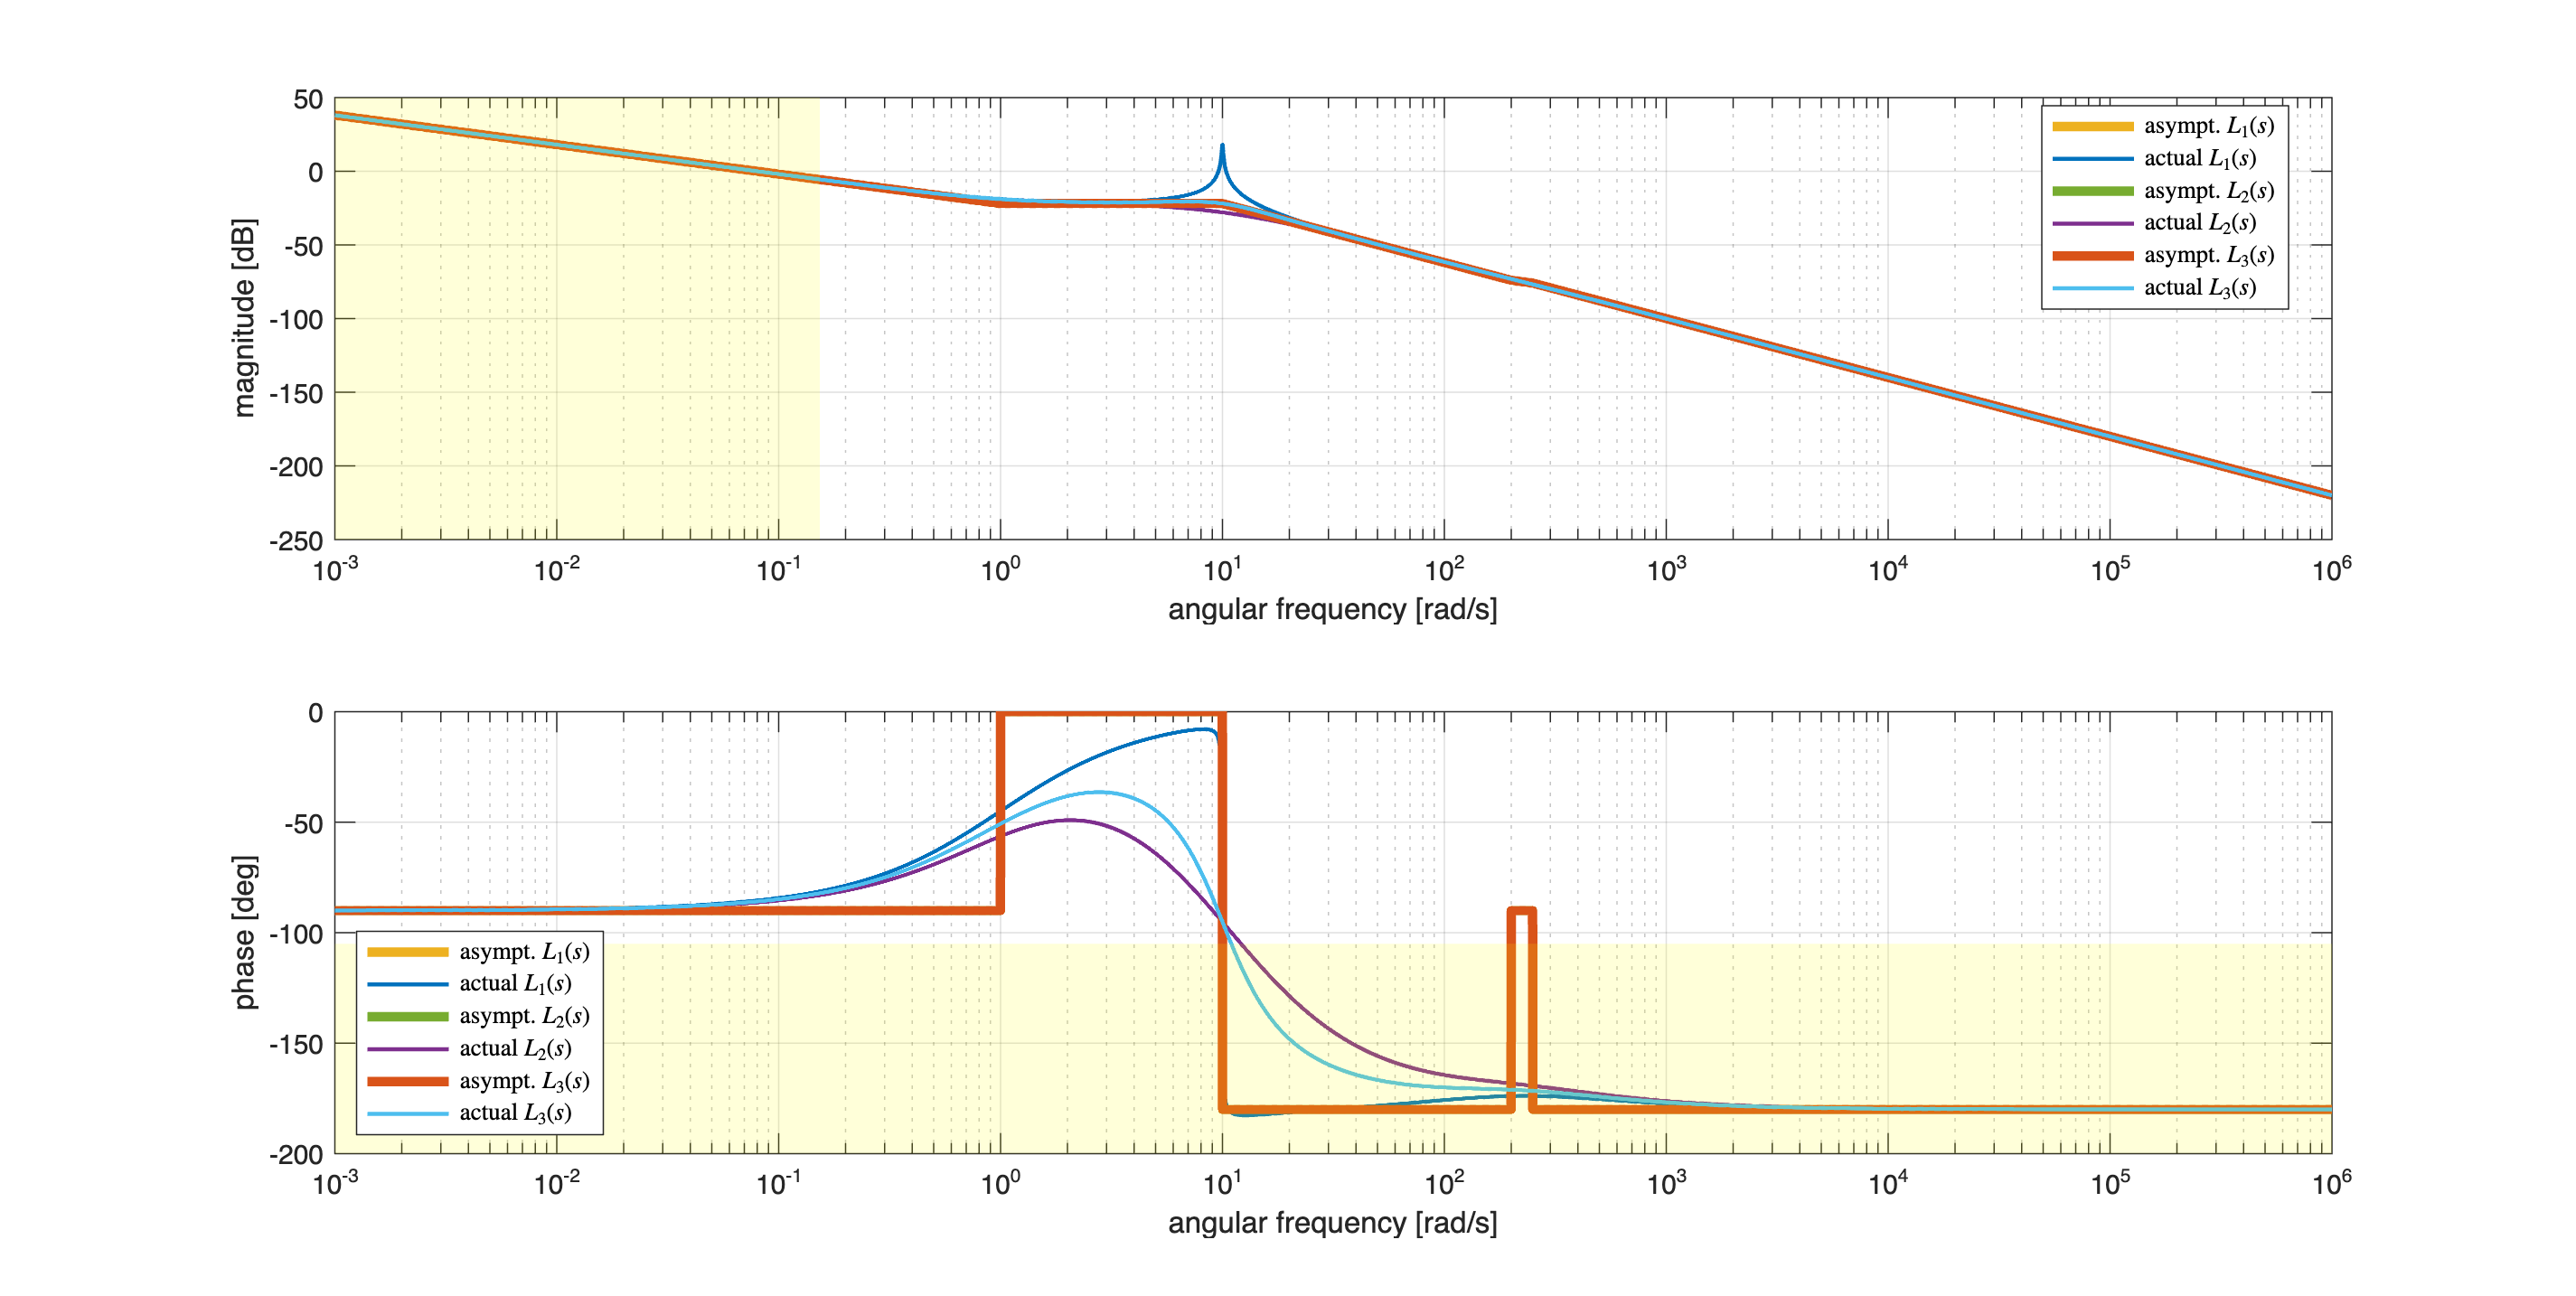

% the Bode diagrams

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                 

hf = figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.85]);
drawBodediagrams(Ls1, [], Bcolors(2,:) , 3.5, [], Bcolors(1,:) ,1.5, [], hf);
drawBodediagrams(Ls2, [], Bcolors(4,:) , 3.5, [], Bcolors(3,:) ,1.5, [], hf);
[ha1, ha2] = drawBodediagrams(Ls3, [], Bcolors(6,:) , 3.5, [], Bcolors(5,:) ,1.5, [], hf);

phaseM = +75; % the desired minimum phase margin, according to (Q1.2)&(Q1.3)
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);
% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

omC1 = 46/300; % constraint (Q1.3)&(Q1.2)
YLIMS = ylim(ha1);
OMLIMs = xlim(ha1);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert2 = [minOmega1 ,  YLIMS(1); omC1 ,YLIMS(1); ...
         omC1 , YLIMS(2); minOmega1 , YLIMS(2)];
Faces2 = [1  2  3  4];
hold on;
patch(ha1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

legend(ha1, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')
legend(ha2, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'southwest')

 The design problem seems feasible, with the simple controller $C_1(s) = \frac{\mu_C}{s}$ if we plan to obtain the crossover angular frequency in the interval $\omega_c \in \big[ 0.2\,,\; 2.0 \big] \; \text{rad/sec}$. 

The worst-case scenario corresponds to the highest value for the damping coefficient $B$, i.e., $B = 1.0$.

With the aim to ease the design, let's insert a term with a zero in the controller, with the zero at $z = -10$

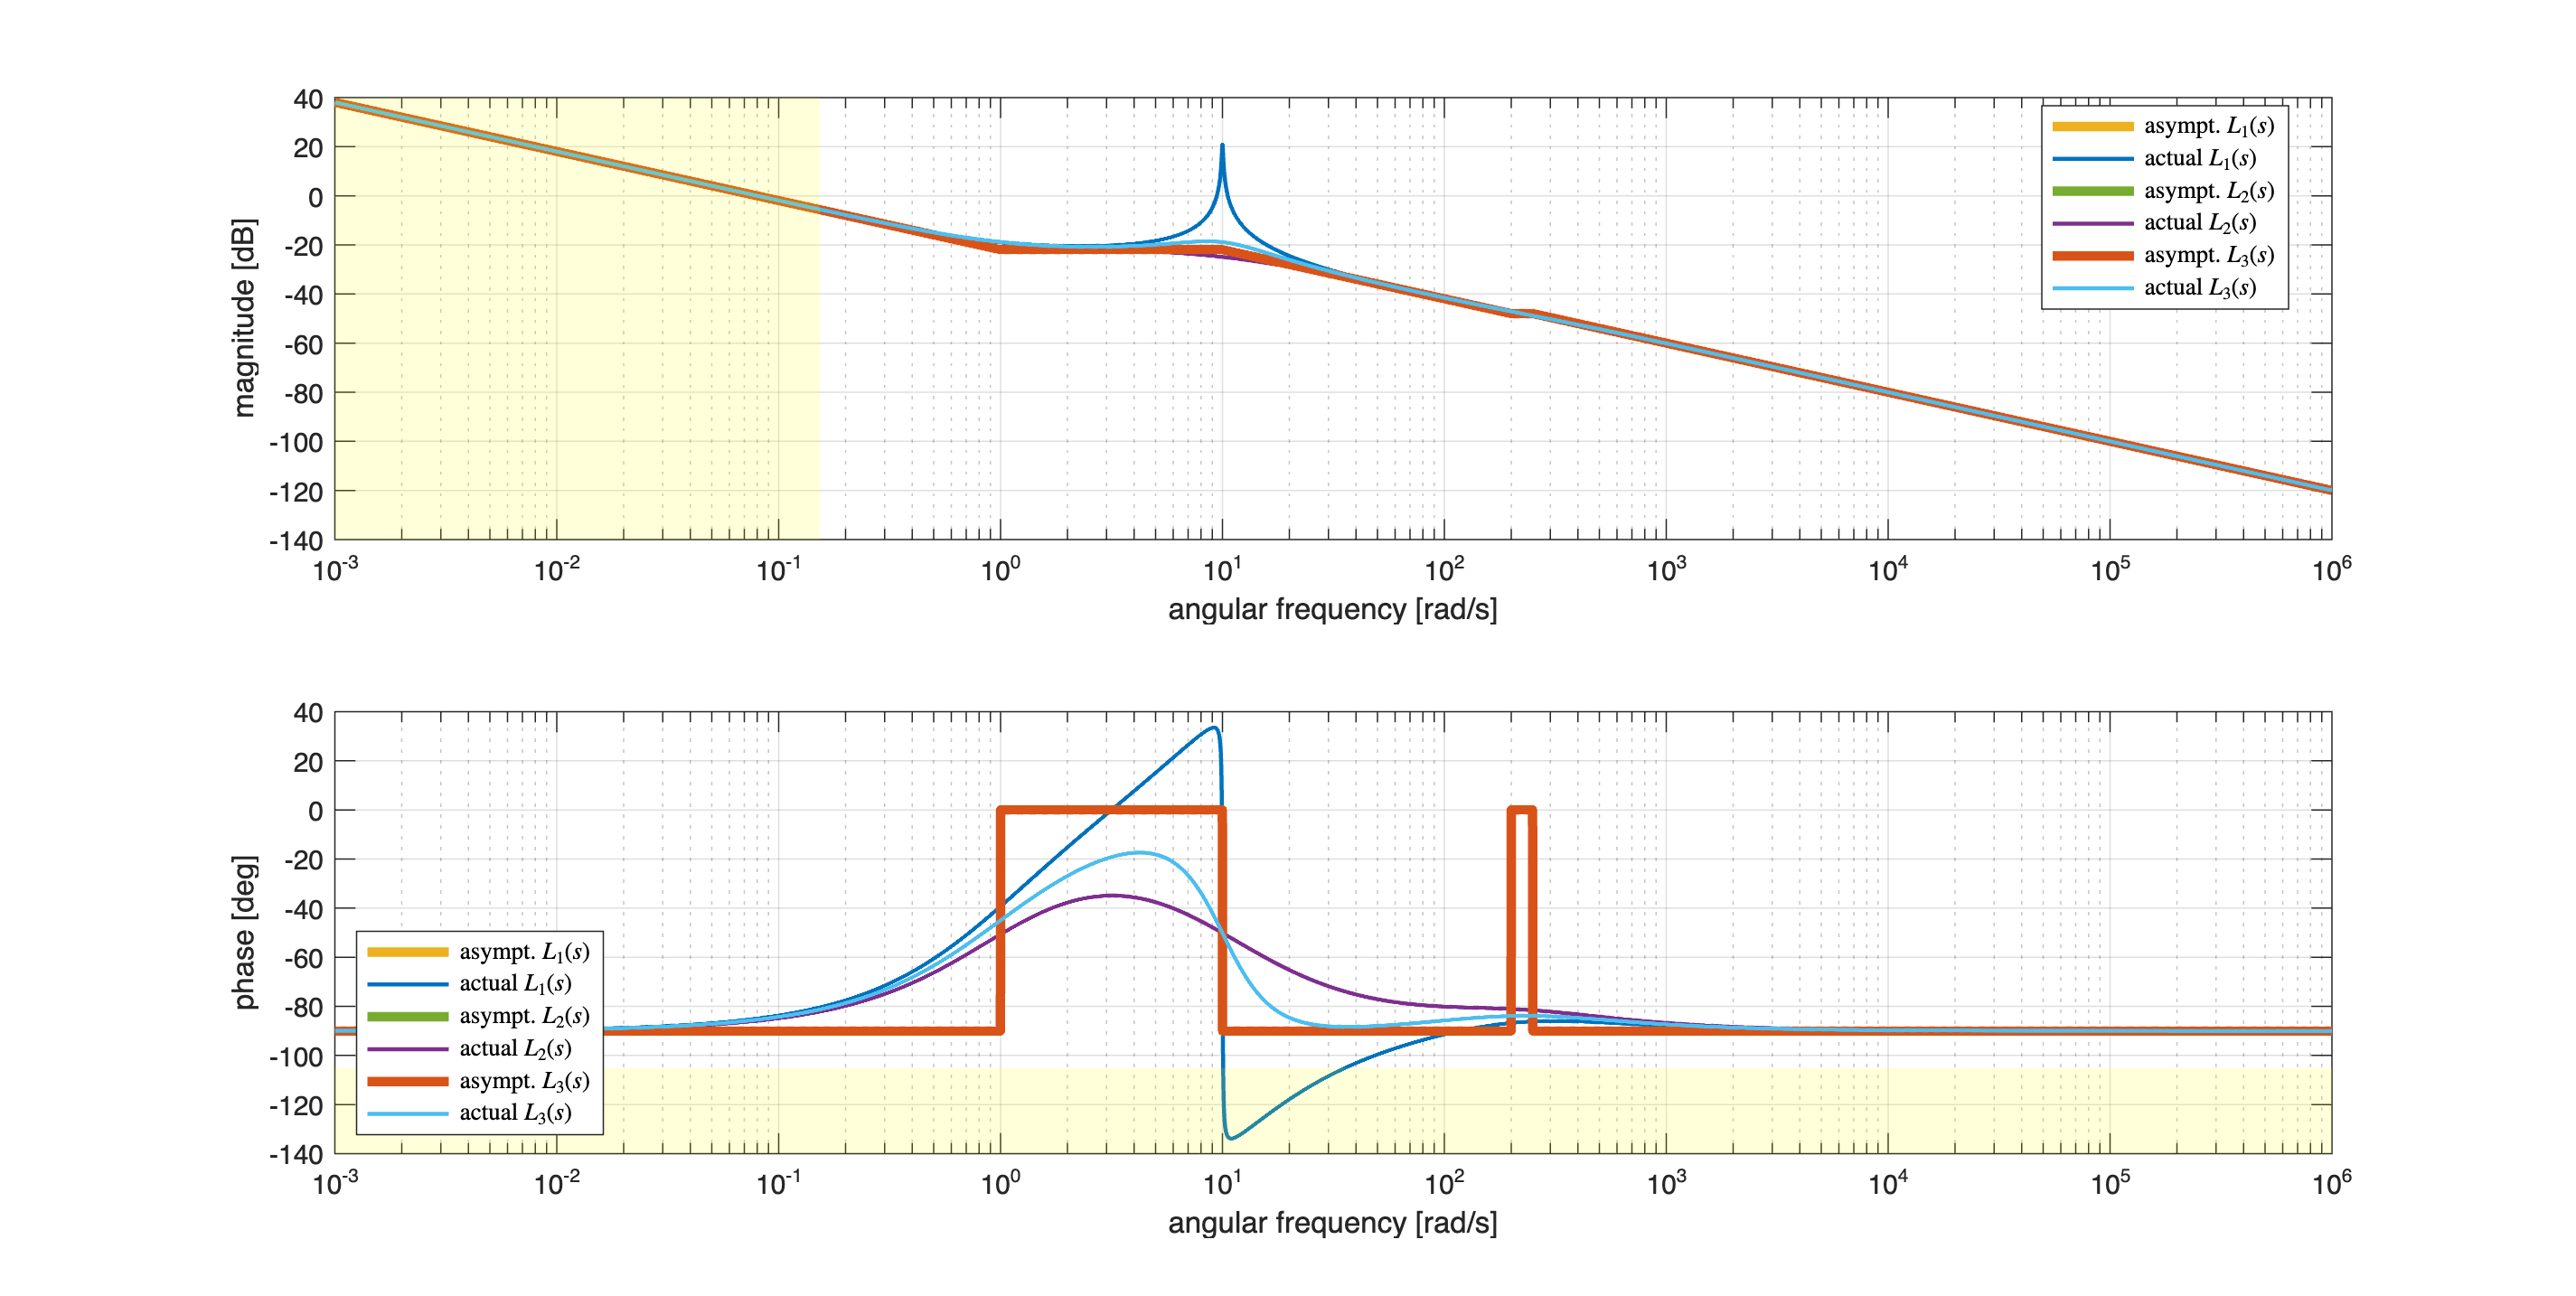

C2s = (1+s/10);
Cs = C1s*C2s;

Ls1NEW = Cs*Gs1;
Ls2NEW = Cs*Gs2;
Ls3NEW = Cs*Gs3;

hf = figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.85]);
drawBodediagrams(Ls1NEW, [], Bcolors(2,:) , 3.5, [], Bcolors(1,:) ,1.5, [], hf);
drawBodediagrams(Ls2NEW, [], Bcolors(4,:) , 3.5, [], Bcolors(3,:) ,1.5, [], hf);
[ha1, ha2] = drawBodediagrams(Ls3NEW, [], Bcolors(6,:) , 3.5, [], Bcolors(5,:) ,1.5, [], hf);

phaseM = +75; % the desired minimum phase margin, according to (Q1.2)&(Q1.3)
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);
% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

omC1 = 46/300; % constraint (Q1.3)&(Q1.2)
YLIMS = ylim(ha1);
OMLIMs = xlim(ha1);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert2 = [minOmega1 ,  YLIMS(1); omC1 ,YLIMS(1); ...
         omC1 , YLIMS(2); minOmega1 , YLIMS(2)];
Faces2 = [1  2  3  4];
hold on;
patch(ha1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

legend(ha1, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')
legend(ha2, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'southwest')

 The design problem seems feasible, with the controller $C(s) = C_1(s) \cdot C_2(s) $ if we plan to obtain the crossover angular frequency in the interval $\omega_c \in \big[ 0.2\,,\; 9.0 \big] \; \text{rad/sec}$ or $\omega_c > 200$ rad/sec.

The worst-case scenario corresponds to the highest value for the damping coefficient $B$, i.e., $B = 1.0$.

An even better design scenario corresponds to the dynamic controller $C_2(s) = \frac{\left (1+\frac{s}{10} \right)^2}{\left(1+\frac{s}{200} \right)$


$$C(s) = \mu_C\,\frac{\left (1+\frac{s}{10} \right)^2}{s\,\left(1+\frac{s}{200} \right)} \quad \Longrightarrow \quad L(s) = 20\,\mu_C\,\frac{\left(s+1 \right)\,\left(s+10\right)^2}{s\,\left(s^2+20B\,s+100\right)\,\left(s+250\right)} \;,\quad B \in \big[0.005\,,\; 1.0 \big]$$


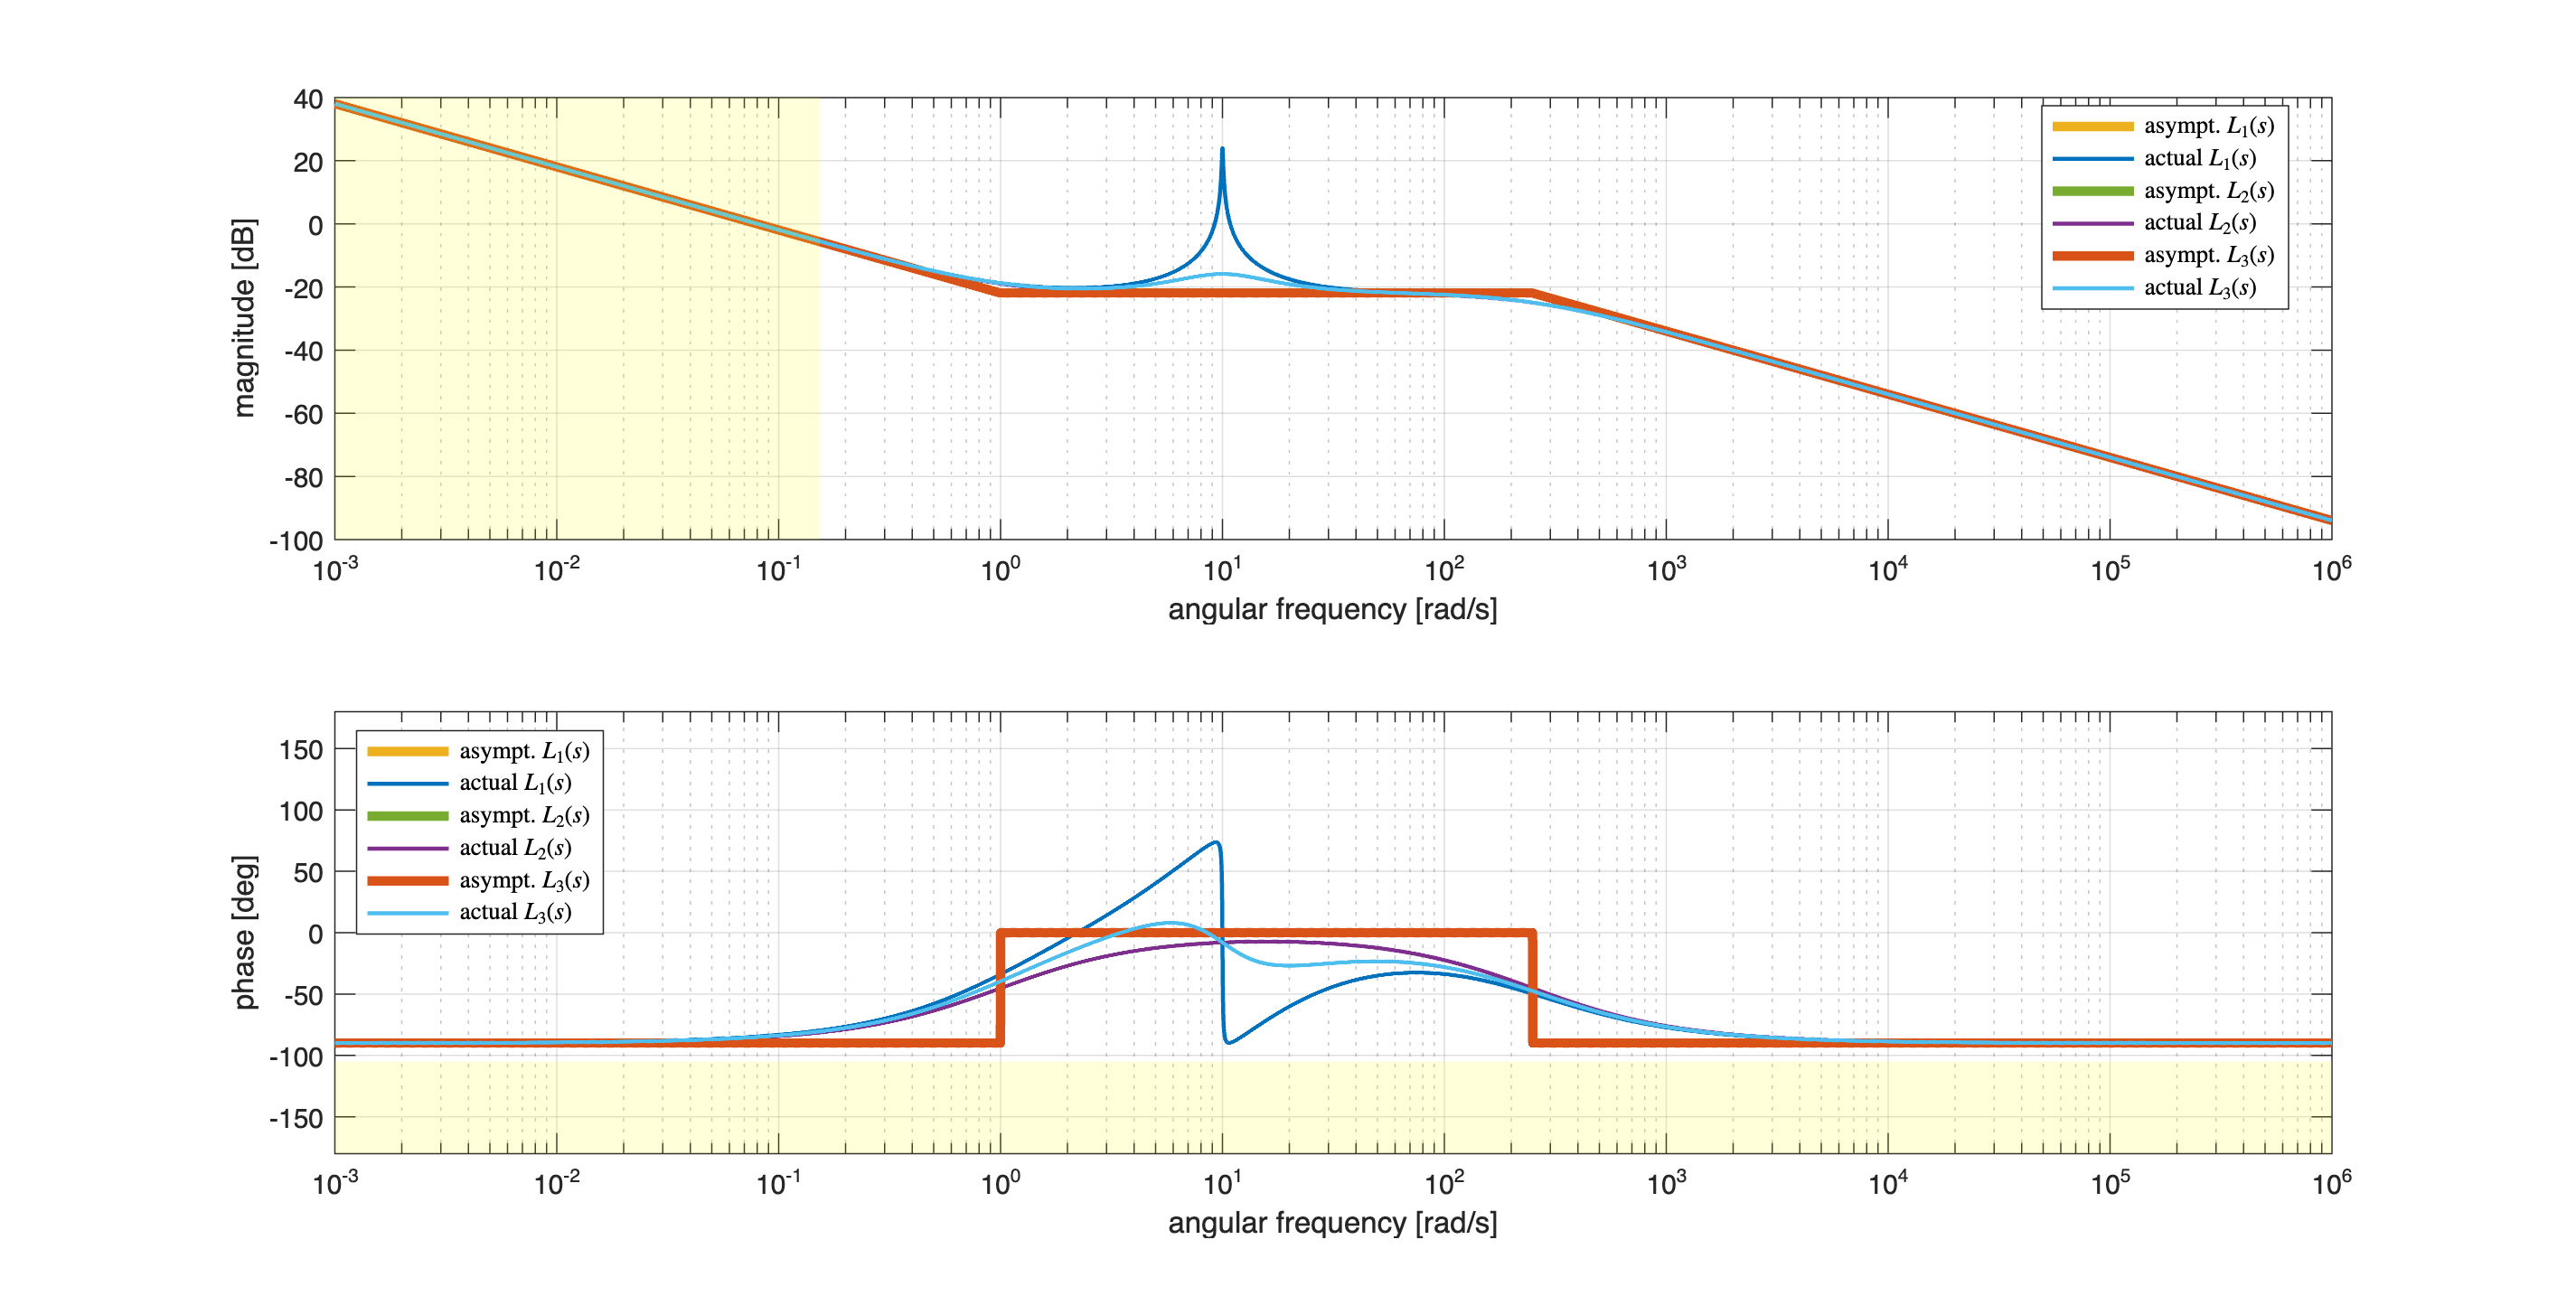

C2s = (1+s/10)^2/(1+s/200);
Cs = minreal(C1s*C2s);

Ls1NEW = Cs*Gs1;
Ls2NEW = Cs*Gs2;
Ls3NEW = Cs*Gs3;

hf = figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.85]);
drawBodediagrams(Ls1NEW, [], Bcolors(2,:) , 3.5, [], Bcolors(1,:) ,1.5, [], hf);
drawBodediagrams(Ls2NEW, [], Bcolors(4,:) , 3.5, [], Bcolors(3,:) ,1.5, [], hf);
[ha1, ha2] = drawBodediagrams(Ls3NEW, [], Bcolors(6,:) , 3.5, [], Bcolors(5,:) ,1.5, [], hf);

phaseM = +75; % the desired minimum phase margin, according to (Q1.2)&(Q1.3)
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design
ylim(ha2, [-180, 180]);
YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);
% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

omC1 = 46/300; % constraint (Q1.3)&(Q1.2)
YLIMS = ylim(ha1);
OMLIMs = xlim(ha1);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert2 = [minOmega1 ,  YLIMS(1); omC1 ,YLIMS(1); ...
         omC1 , YLIMS(2); minOmega1 , YLIMS(2)];
Faces2 = [1  2  3  4];
hold on;
patch(ha1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

legend(ha1, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')
legend(ha2, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'northwest')

In this scenario, we can guarantee the phase margin $\bar \varphi_m = +90^\circ$ when $\omega_c \ge 0.2$ rad/sec.

What about the second scenario in Eq. $(*)$? Consider the minimum allowable value for the phase margin:


$$\varphi_m = 30^{\circ} \quad \Longrightarrow \quad \omega_c \ge \frac{46}{90} \approx 0.512\; \text{rad/sec}$$


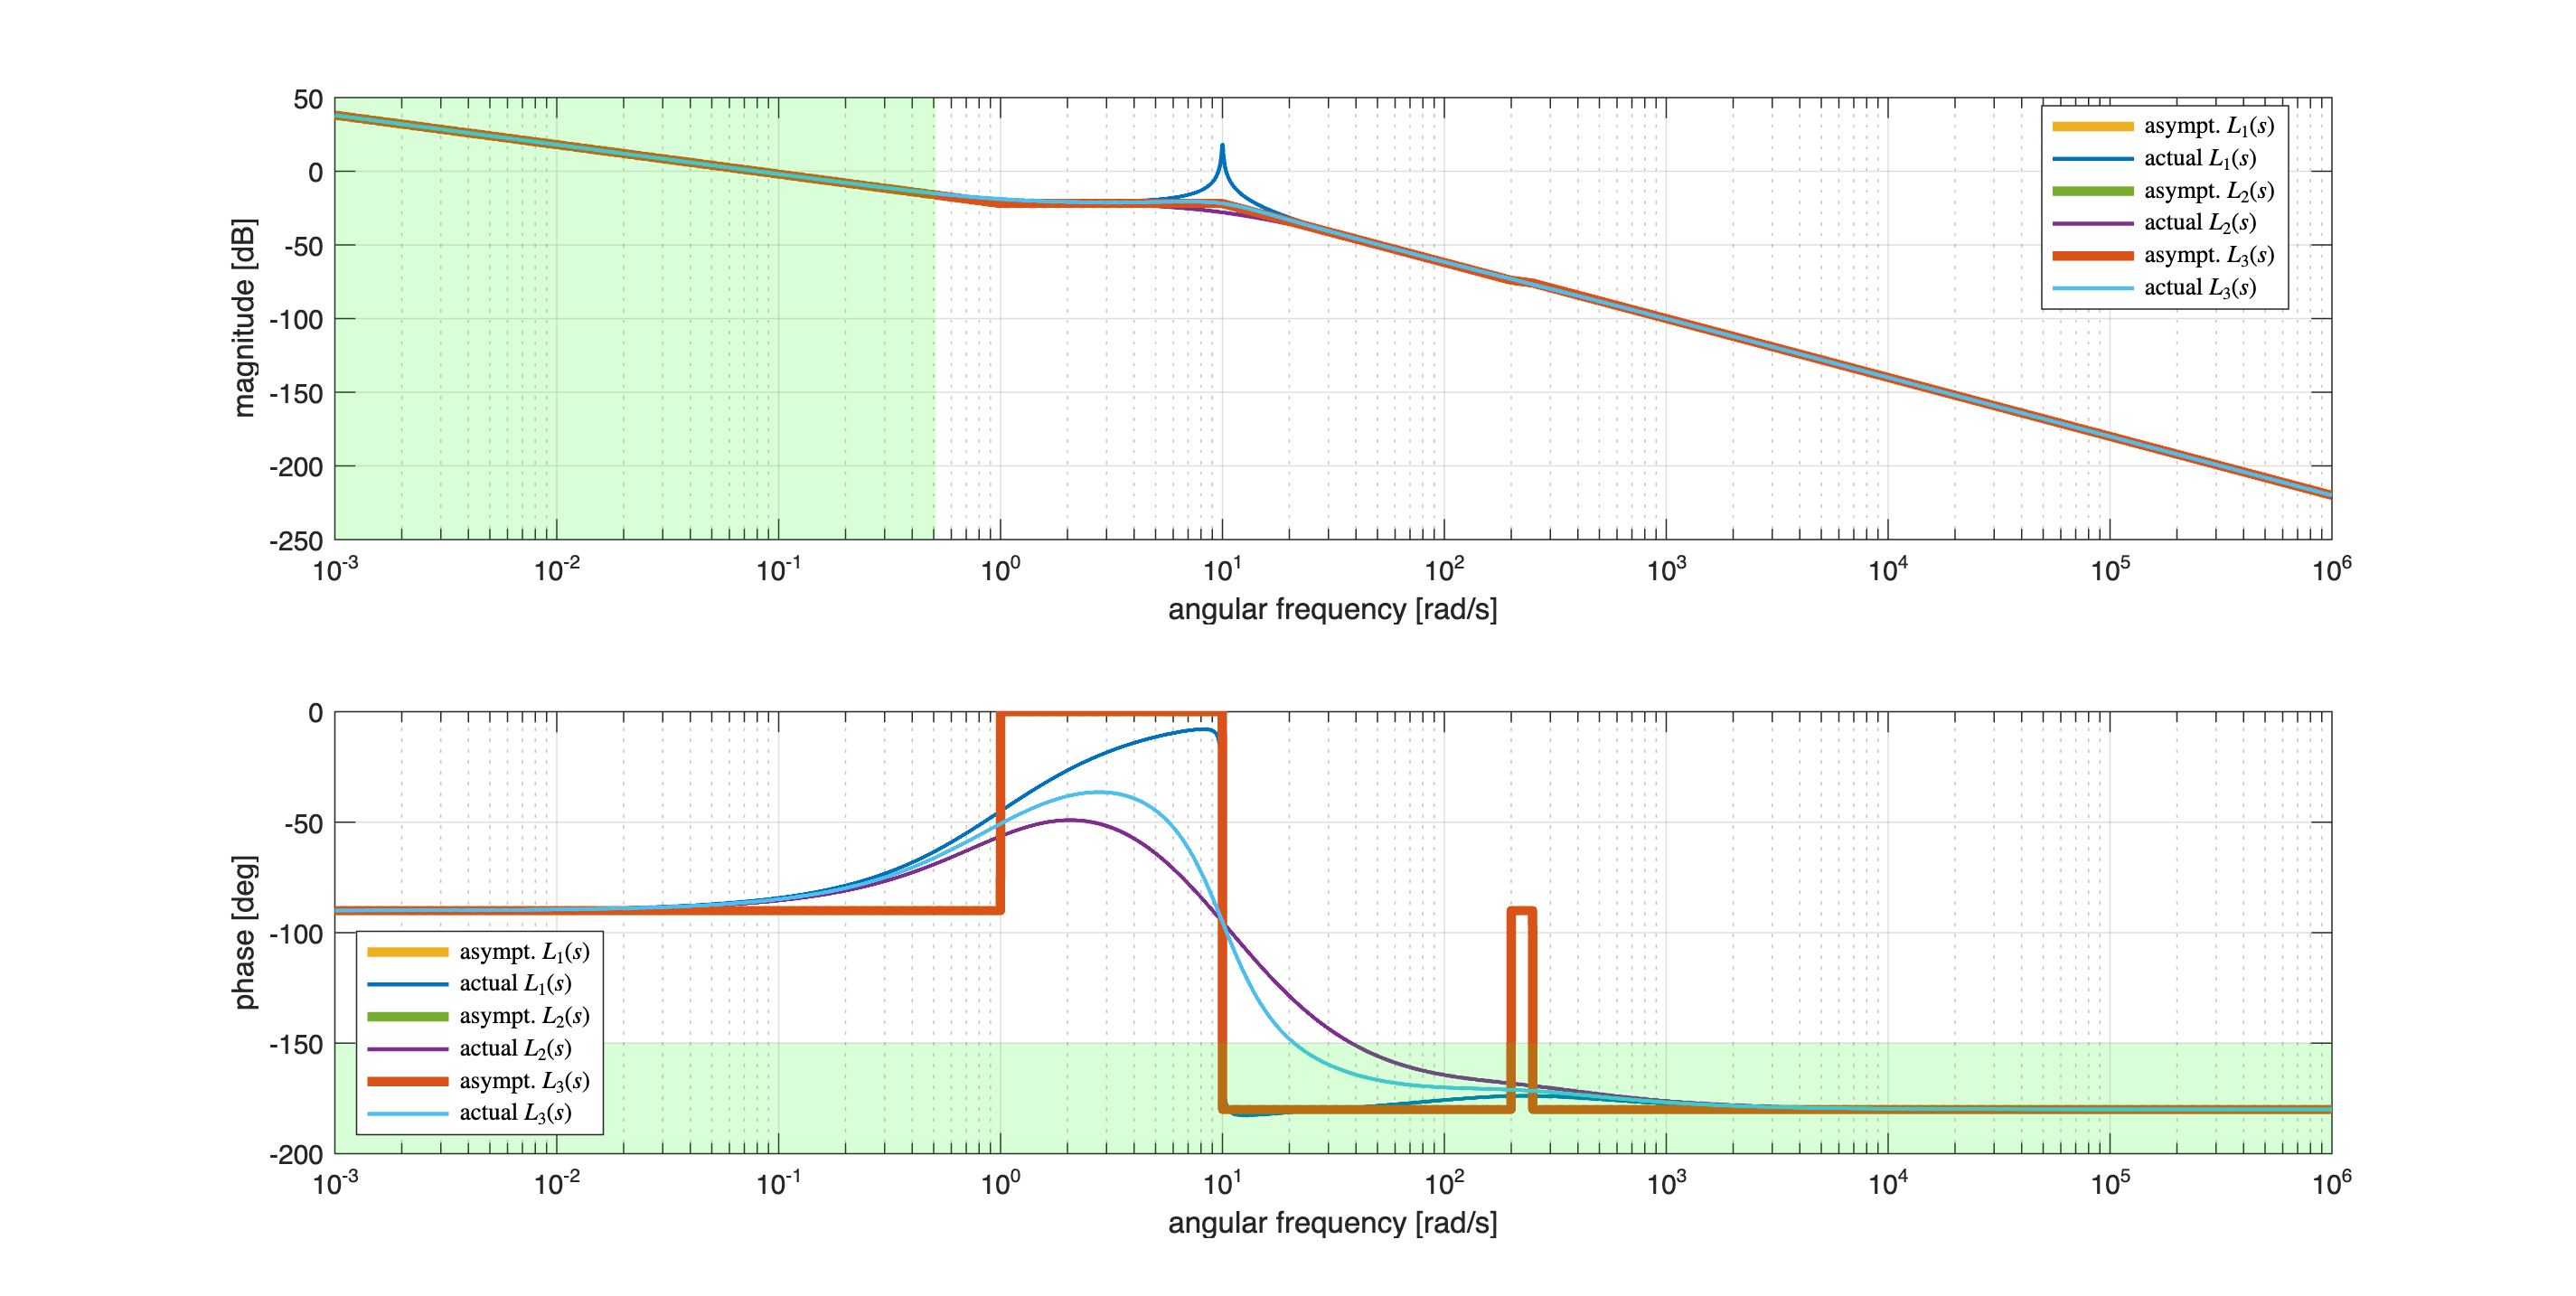

hf = figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.85]);
drawBodediagrams(Ls1, [], Bcolors(2,:) , 3.5, [], Bcolors(1,:) ,1.5, [], hf);
drawBodediagrams(Ls2, [], Bcolors(4,:) , 3.5, [], Bcolors(3,:) ,1.5, [], hf);
[ha1, ha2] = drawBodediagrams(Ls3, [], Bcolors(6,:) , 3.5, [], Bcolors(5,:) ,1.5, [], hf);

phaseM = +30; % the desired minimum phase margin, according to (Q1.2)&(Q1.3)
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);
% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','green','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

omC1 = 0.512; % constraint (Q1.3)&(Q1.2)
YLIMS = ylim(ha1);
OMLIMs = xlim(ha1);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert2 = [minOmega1 ,  YLIMS(1); omC1 ,YLIMS(1); ...
         omC1 , YLIMS(2); minOmega1 , YLIMS(2)];
Faces2 = [1  2  3  4];
hold on;
patch(ha1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','green','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

legend(ha1, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')
legend(ha2, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'southwest')

 Also this time, the design problem is feasible, with the simple controller $C_1(s) = \frac{\mu_C}{s}$ if we plan to obtain the crossover angular frequency in the interval $\omega_c \le 5.0  \; \text{rad/sec}$.

The worst-case scenario corresponds to the highest value for the damping coefficient $B$, i.e., $B = 1.0$.

### Tuning the Controller

According to the previously performed analysis, the controller


$$C(s) = \mu_C\,\frac{\left (1+\frac{s}{10} \right)^2}{s\,\left(1+\frac{s}{200} \right)} $$


allows the fulfilment of all the requirements, with the phase margin $\bar \varphi_m = +90^\circ$ when $\omega_c \ge 0.2$ rad/sec.

Let's tune the gain constant $\mu_C$ with the aim to obtain $\bar \omega = 10.0$ rad/sec as crossover frequency in the worst-case scenario:

barOMc1 = 1j*10;
mag_L2s_barOMc1 = abs(freqresp(Ls2NEW, barOMc1));
muC_VAL = 1/mag_L2s_barOMc1

muC_VAL = 12.4479

Verify the performance of the controller $C_1(s)$ in every scenario

Cs = muC_VAL*Cs; 

Ls1FINAL = Cs*Gs1;
Ls2FINAL = Cs*Gs2;
Ls3FINAL = Cs*Gs3;

[gm, pm, o_gm, o_pm] = margin(Ls1FINAL)

gm = Inf

pm = 147.3499

o_gm = NaN

o_pm = 69.5526


[gm2, pm2, o_gm2, o_pm2] = margin(Ls2FINAL)

gm2 = Inf

pm2 = 171.9989

o_gm2 = NaN

o_pm2 = 10.0002


[gm3, pm3, o_gm3, o_pm3] = margin(Ls3FINAL)

gm3 = Inf

pm3 = 156.0696

o_gm3 = NaN

o_pm3 = 64.1841

In conclusion, the controller $C(s)$ allows to fulfil every requirement.

### Fine Tuning the Controller using the controlSystemDesigner App

% let's create a multi-model structure
Gs = stack(1, Gs1, Gs2, Gs3);

controlSystemDesigner(Gs, Cs)

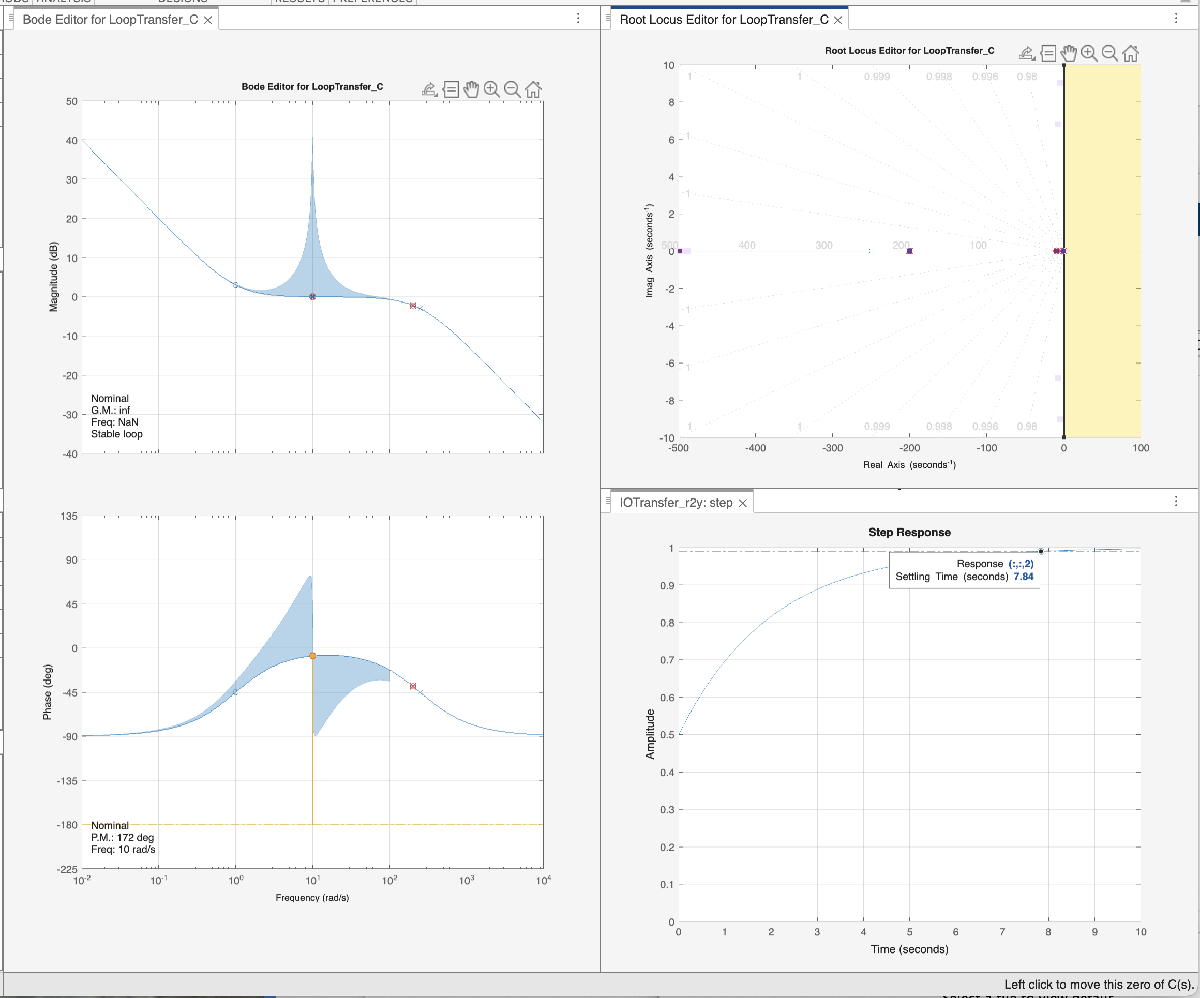

The corresponding controlSystremDesigner session file is `multimodel_solution_2025_06_06_FA_gr_C_ControlSystemDesignerSession.mat`